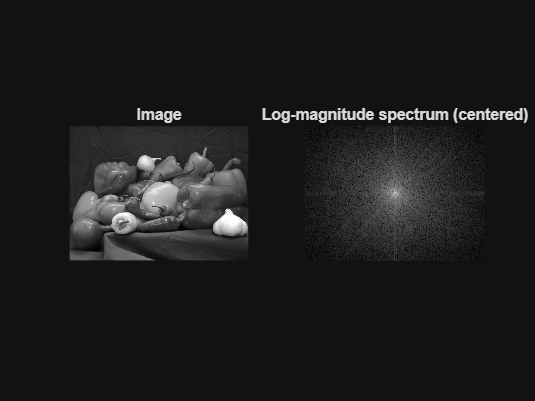

%% Lab 3: Frequency-Domain Filtering with fft2
% Course: Mathematical Algorithms (DSP) — Image Processing Labs
% -------------------------------------------------------------------------
% - Ideal LP causes ringing (Gibbs) due to hard cutoff.
% - Convolution theorem: spatial convolution <-> frequency multiplication.
% - Compare spatial vs frequency-domain Gaussian LP (should match closely).
% HOW TO SUBMIT: include screenshots and short explanations for each section in the GitHub. Submit only the GitHub URL.
% -------------------------------------------------------------------------
close all; clear; clc;
if exist('peppers.png','file')
    I0 = imread('peppers.png');
else
    I0 = repmat(imread('cameraman.tif'),1,1,3);
end
I = im2double(rgb2gray(I0));
[M,N] = size(I);
%% 1) Magnitude spectrum (log-scale)
F = fft2(I);
Fshift = fftshift(F);
S = log(1 + abs(Fshift));
figure;
subplot(1,2,1); imshow(I,[]); title('Image');
subplot(1,2,2); imshow(S,[]); title('Log-magnitude spectrum (centered)');

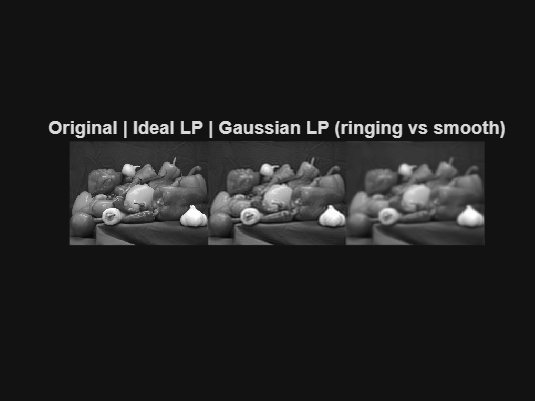

%% 2) Ideal & Gaussian Low-pass in frequency
[u,v] = meshgrid( (-floor(N/2)) : (ceil(N/2)-1), (-floor(M/2)) : (ceil(M/2)-1) );
D = sqrt(u.^2 + v.^2);
D0 = 40; % cutoff radius
H_ideal_LP = double(D <= D0); % ideal circular LP
sigma = 20;
H_gauss_LP = exp(-(D.^2) / (2*sigma^2));
%% 3) Apply LP filters in frequency domain
G_ideal = ifft2( ifftshift( H_ideal_LP .* Fshift ) );
G_gauss = ifft2( ifftshift( H_gauss_LP .* Fshift ) );
figure; montage({I, real(G_ideal), real(G_gauss)}, 'Size', [1 3]);
title('Original | Ideal LP | Gaussian LP (ringing vs smooth)');

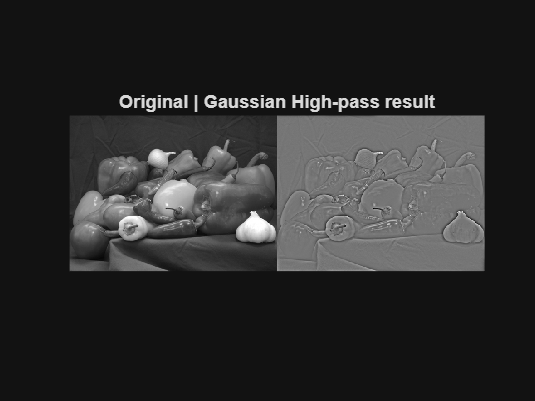

%% 4) High-pass via complement
H_gauss_HP = 1 - H_gauss_LP;
G_hp = real( ifft2( ifftshift( H_gauss_HP .* Fshift ) ) );
G_hp = mat2gray(G_hp);
figure; montage({I, G_hp}, 'Size', [1 2]);
title('Original | Gaussian High-pass result');

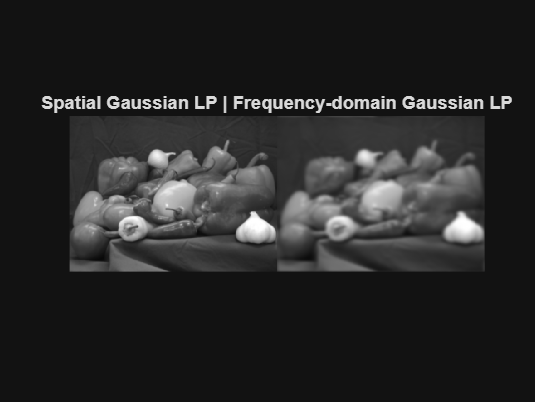

%% 5) Compare spatial vs frequency-domain Gaussian LP
g1d = fspecial('gaussian',[1 7], 1.2);
I_spatial_gauss = imfilter(I, g1d'*g1d, 'replicate');
figure; montage({I_spatial_gauss, real(G_gauss)}, 'Size', [1 2]);
title('Spatial Gaussian LP | Frequency-domain Gaussian LP');

%% 6) Reflections
% 1) Why does ideal LP cause ringing (Gibbs phenomenon)?
% Ideal LP causes ringing (Gibbs) due to hard cutoff. 
% 2) What does fftshift do visually?
% It switches the four corners of the image diagonally to centralize the
% low frequency part.
% 3) When is frequency-domain filtering computationally preferable?
% It can make the time complexity from O(MNPQ), M*N being the image size and P*Q being the core size, to O(MN*log(MN)). 
